## Exploring multi-agent behavior

Exercises and demos by Emily Mackevicius, guest lecturing for the Analysis for Neuroscience course at Columbia University. Course Instructors: Itamar Kahn, Ashok Litwin-Kumar, Aniruddha Das.

Multi-agent behaviors are ubiquitous across the evolutionary tree, with spatial scales ranging from microscopic to global. In these exercises, we'll simulate several simple multi-agent behaviors, with the goal of practicing general-purpose analysis and coding skills along the way.

### Skills we'll practice

- Visualize data

- Use and adapt existing code

- Reason about how agents' decision-making policies, and environmental features, generate behaviors

- Translate ideas into code

### Types of multi-agent behaviors we'll explore

- Random walkers -- diffusion

- Random walkers -- levy flight

- Odor-seeking -- environmental gradient

- Odor-seeking -- following pheromones

### Organization of code

- Demos and exercises in `demo.mlx.`

- The main simulation function is `simulate_agents.m.` 

- Relevant information is stored in MATLAB structs `state`, `sensation`, and `action`. 

- This information transforms through time with `perception`, `policy`, and `physics` functions

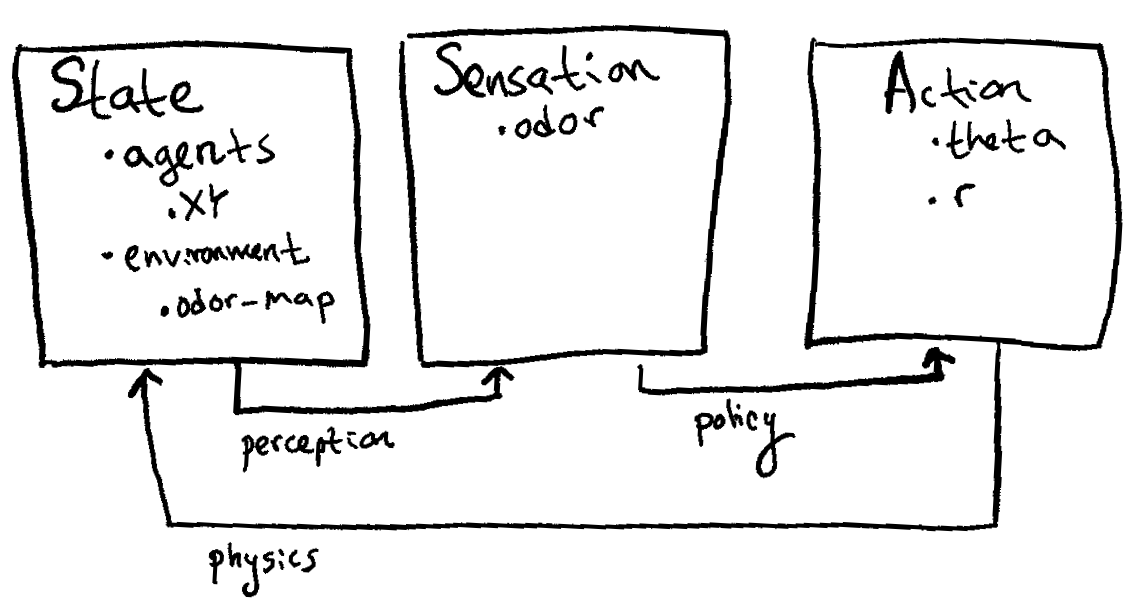

## Demo 1: random walkers

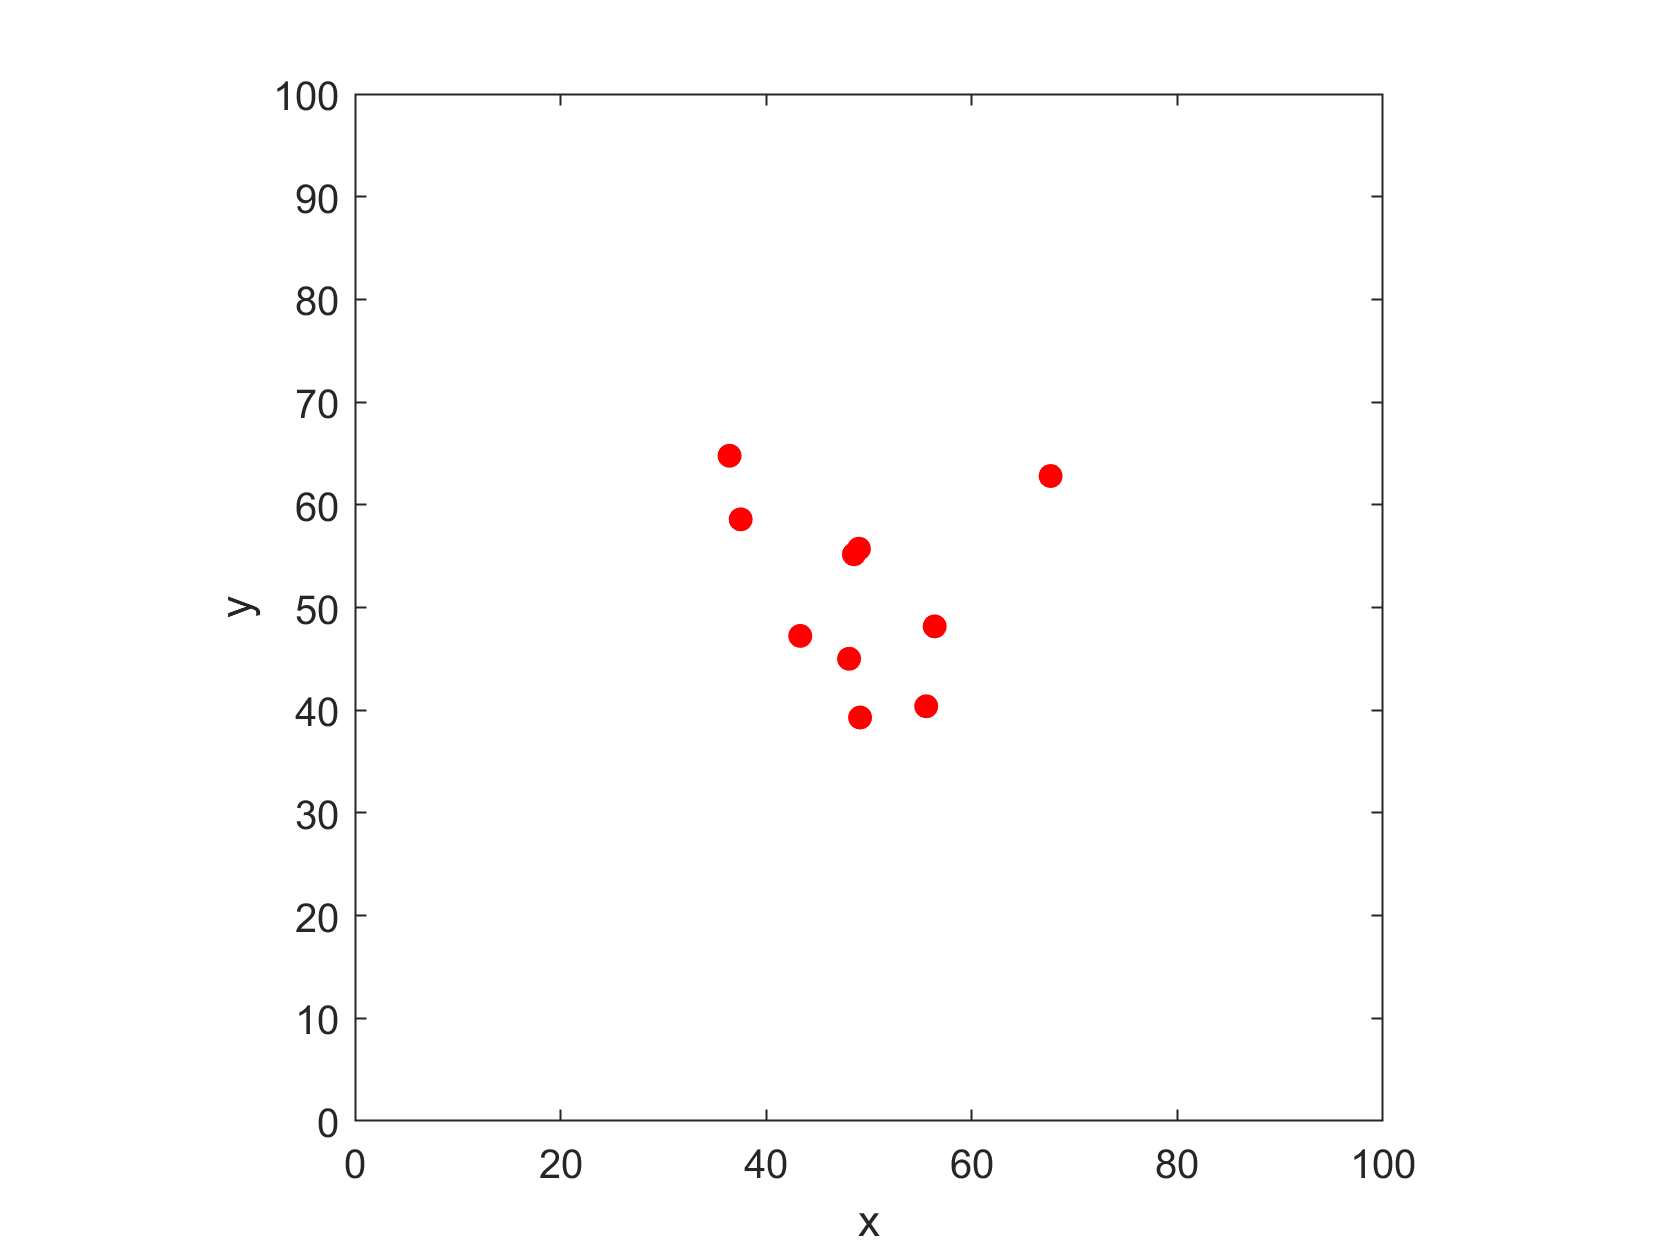

% parameters
n_agents = 10;
n_timesteps = 50;
xy_max = 100;
start_pos_min = 0.4*xy_max;
start_pos_max = 0.6*xy_max;
type_of_agents = 'diffusion'; % try also 'levy'
env_type = 'empty'; 
sensory_range = 0; 
plot_realtime = 1; % it'll run faster if this is 0

XY_all = simulate_agents(n_agents, n_timesteps, xy_max, start_pos_min, start_pos_max, ...
    type_of_agents, env_type, sensory_range, plot_realtime);


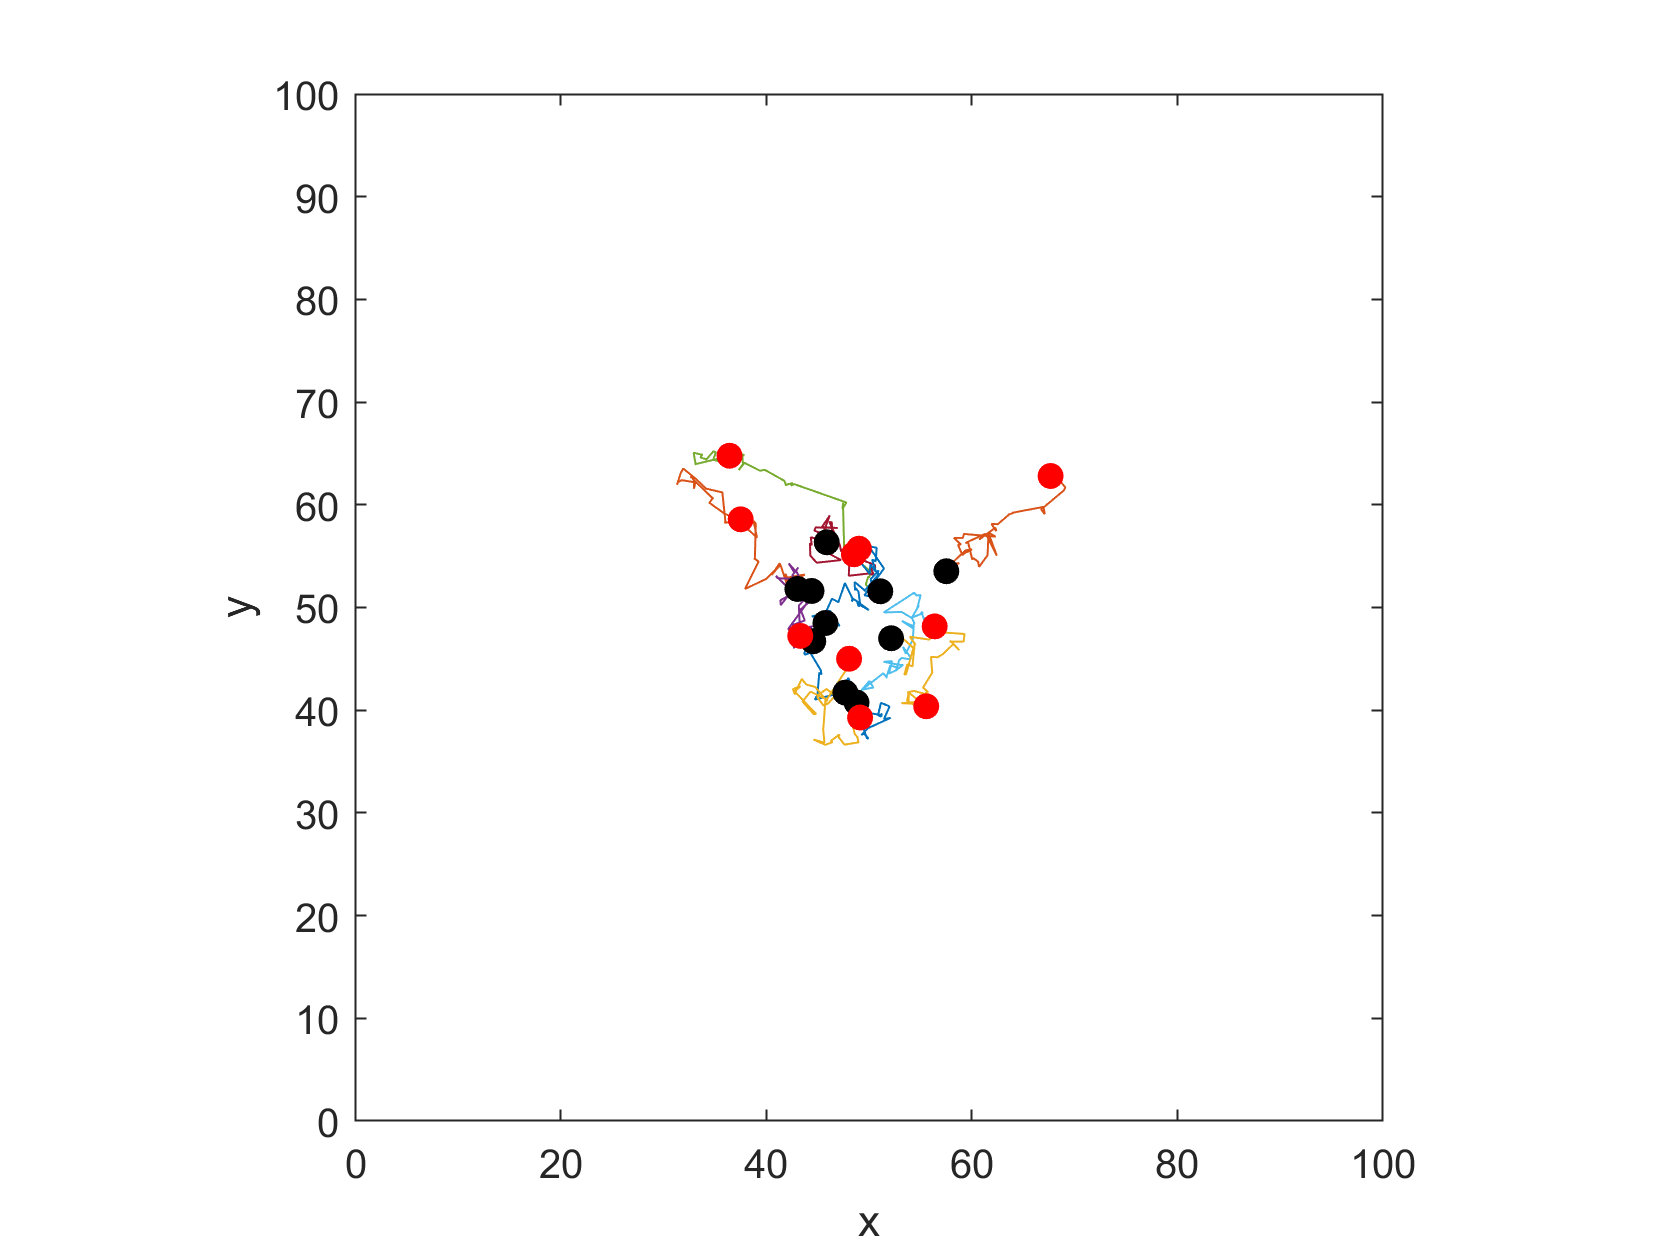

% trajectory plot
figure
plot_trajectories(XY_all, xy_max)


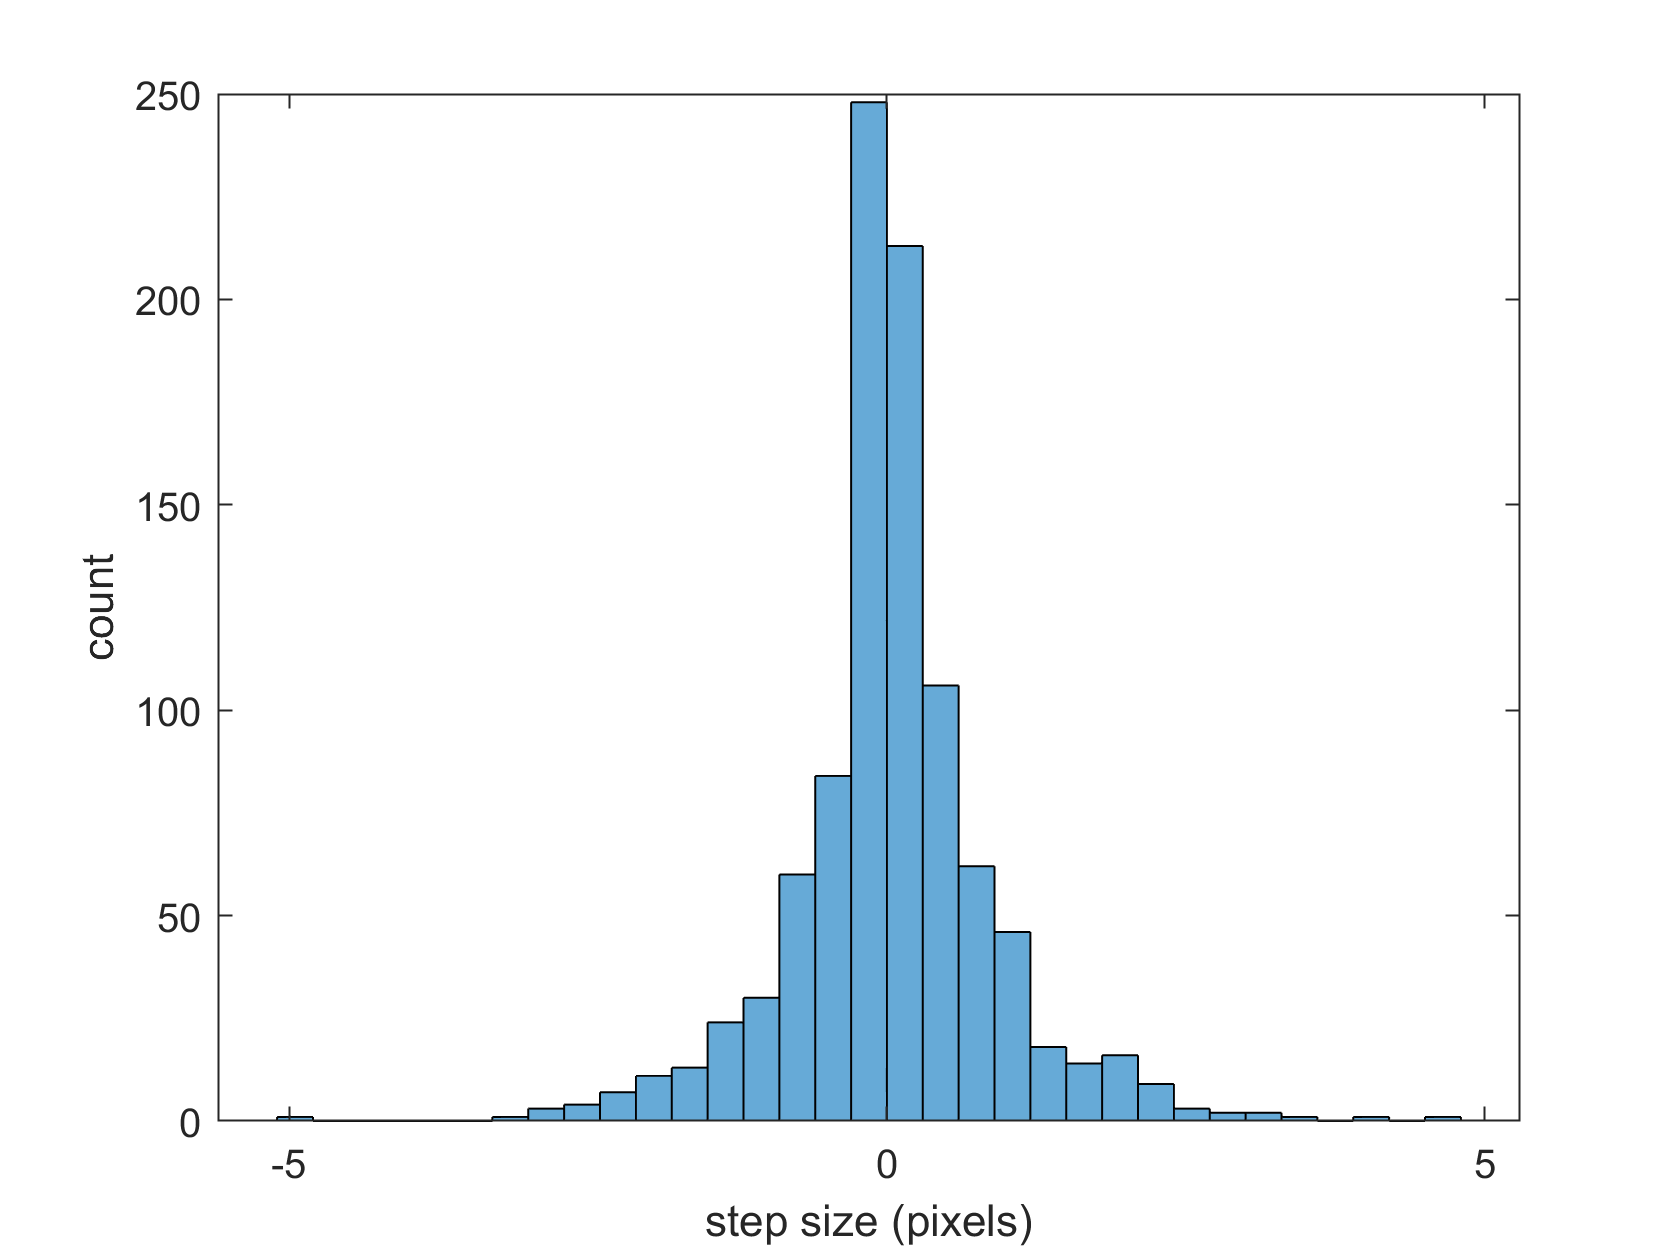

% histogram of step sizes
diffs = diff(XY_all, 1, 2); 
figure
histogram(diffs(:))
xlabel('step size (pixels)')
ylabel('count')


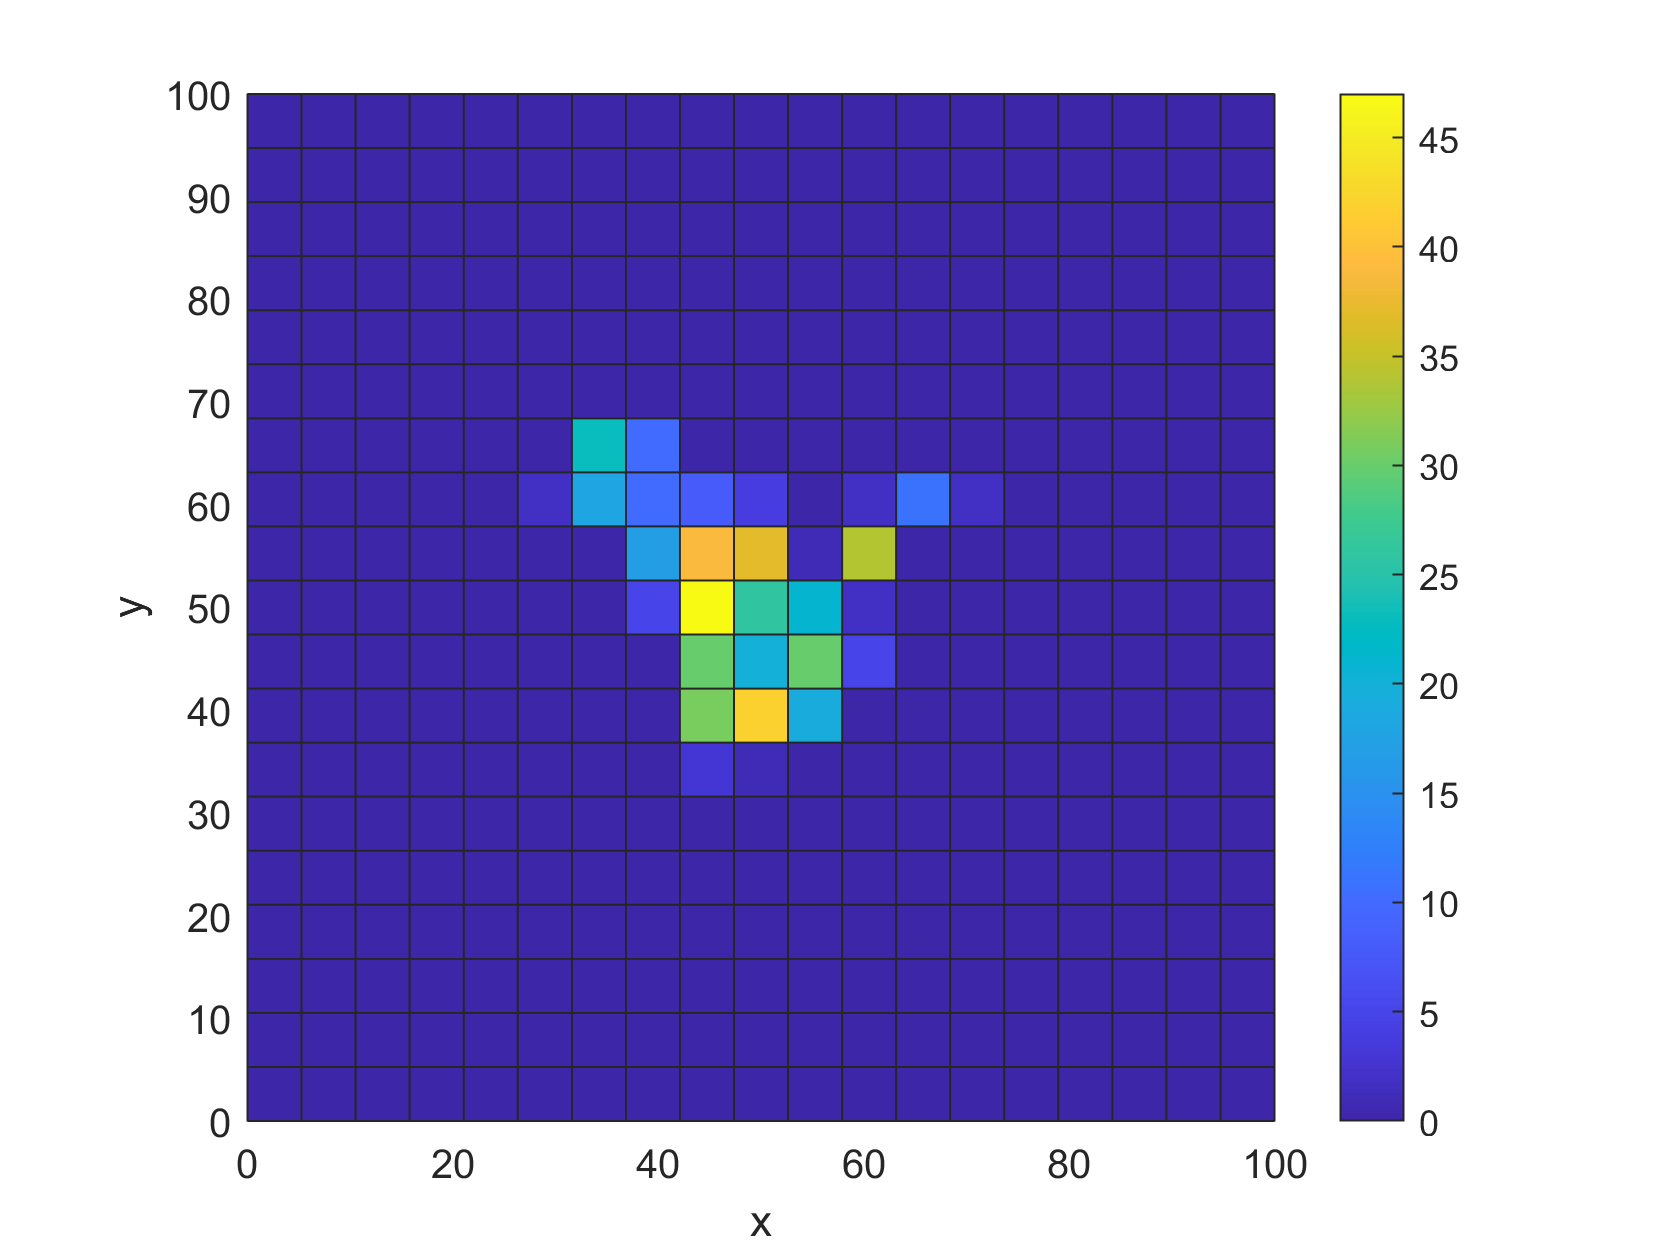

% 2D histogram of locations
nbins = 20; 
figure
plot_heatmap(XY_all, xy_max, nbins)


## Exercises 1

- Simulate 10 random walking agents that move with diffusion, and 10 that move with a levy walk

- From the trajectory plot, which agent appears to explore more efficiently? 

- Compare the histograms of step sizes for the different types of agents. 

- Compare the heatmaps of locations for the different types of agents.

- If you double the duration of the simulation, how much farther does each type of agent spread?

% Your code here, feel free to copy from above


## Demo 2: odor-seeking

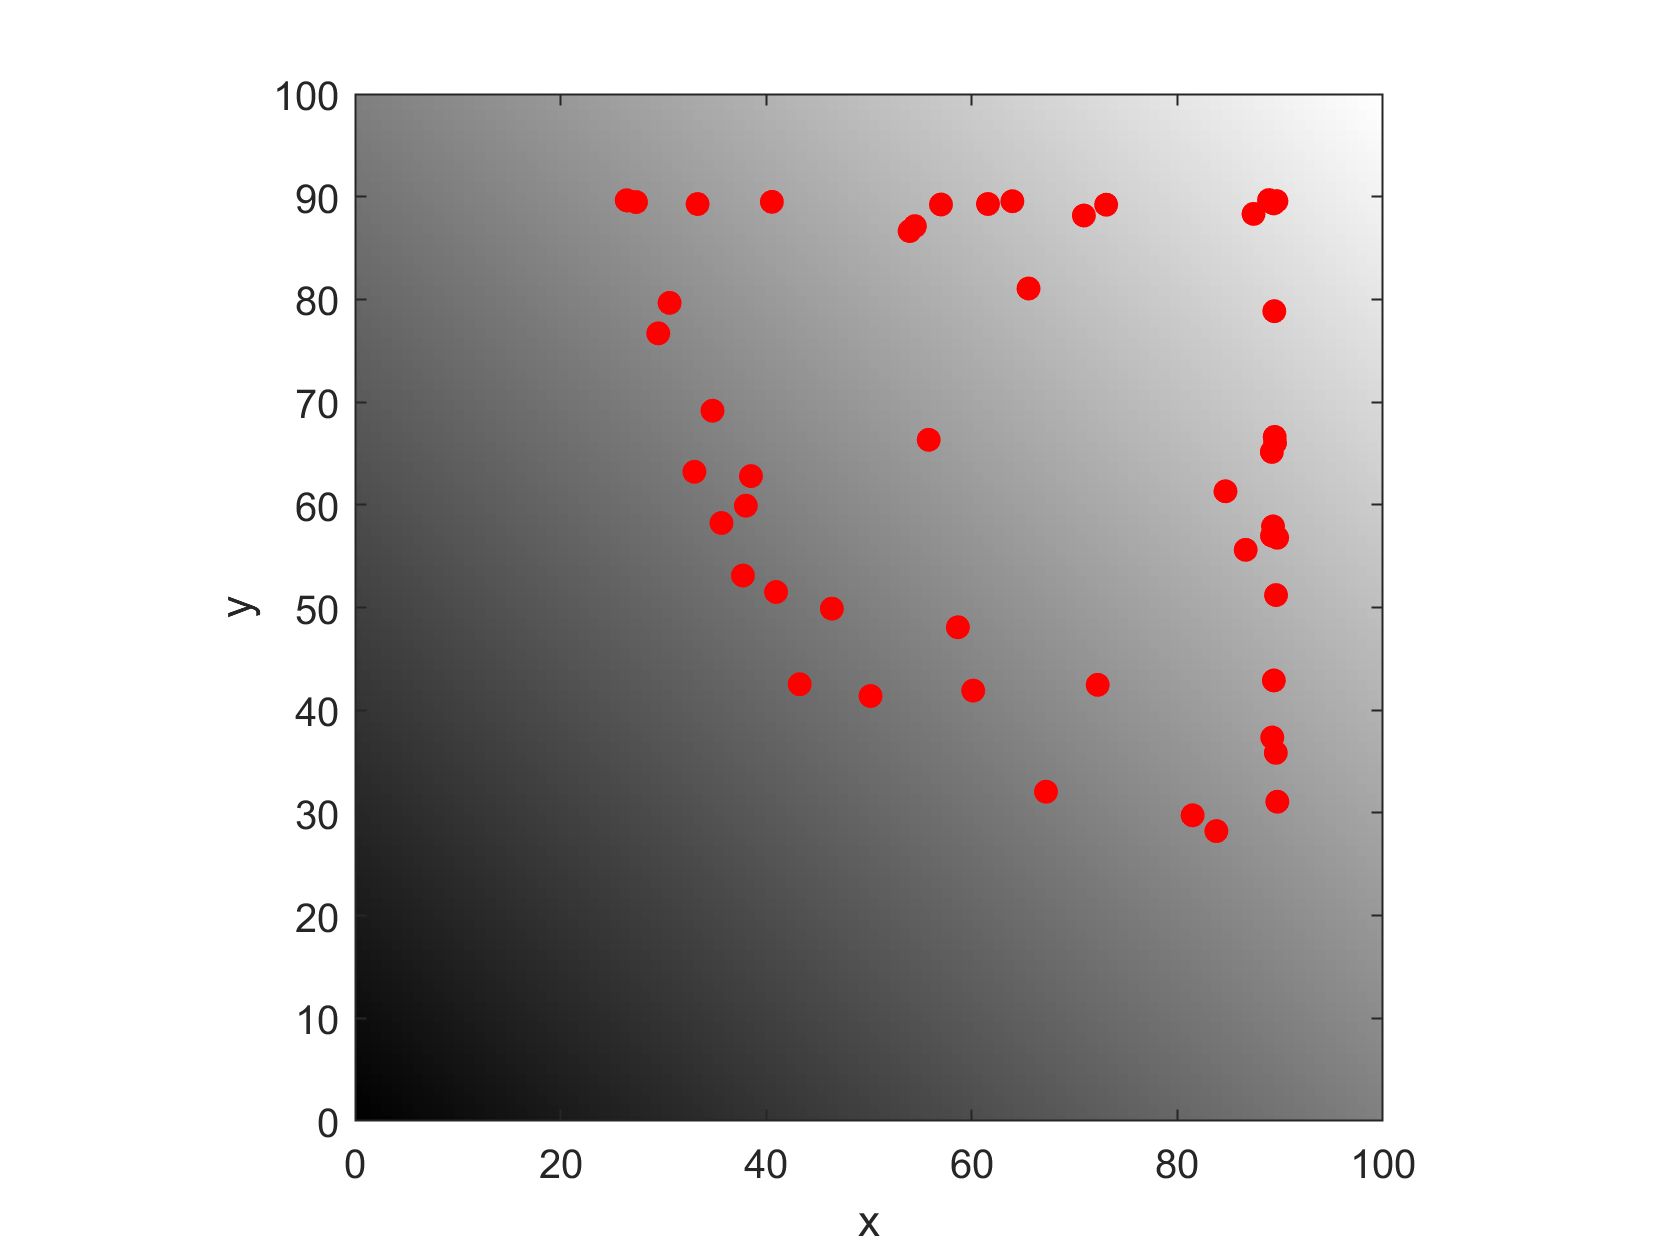

% parameters
n_agents = 50;
n_timesteps = 50;
xy_max = 100;
start_pos_min = 0;
start_pos_max = xy_max;
type_of_agents = 'seek_odor';
env_type = 'gradient'; % also try 'plume'
sensory_range = 10; 
plot_realtime = 1; 

XY_all = simulate_agents(n_agents, n_timesteps, xy_max, start_pos_min, start_pos_max, ...
    type_of_agents, env_type, sensory_range, plot_realtime);

% trajectory plot
figure
plot_trajectories(XY_all, xy_max)


## Exercises 2

- How does the environment impact the behavior of the agents? 

- Use the code below to plot histograms of the distances between agents. The code to compute the distances between the agents is inefficient. Try to make it run faster. Feel free to use LLM tools, discussions with colleagues, etc. for help understanding how it works, and how to make it faster. Remember to label your axes.

- Is the distribution of distances between agents different for the 'gradient' vs 'plume' environments?

- Try inputting your own versions of plume.png, and observe the behavior.

- Draw or select two different images (use any tool you like, e.g. paint, internet search). One should make the agents move together, and another should get the agents to move apart. Validate your results by showing the trajectories, and the histograms of the distances between agents. 

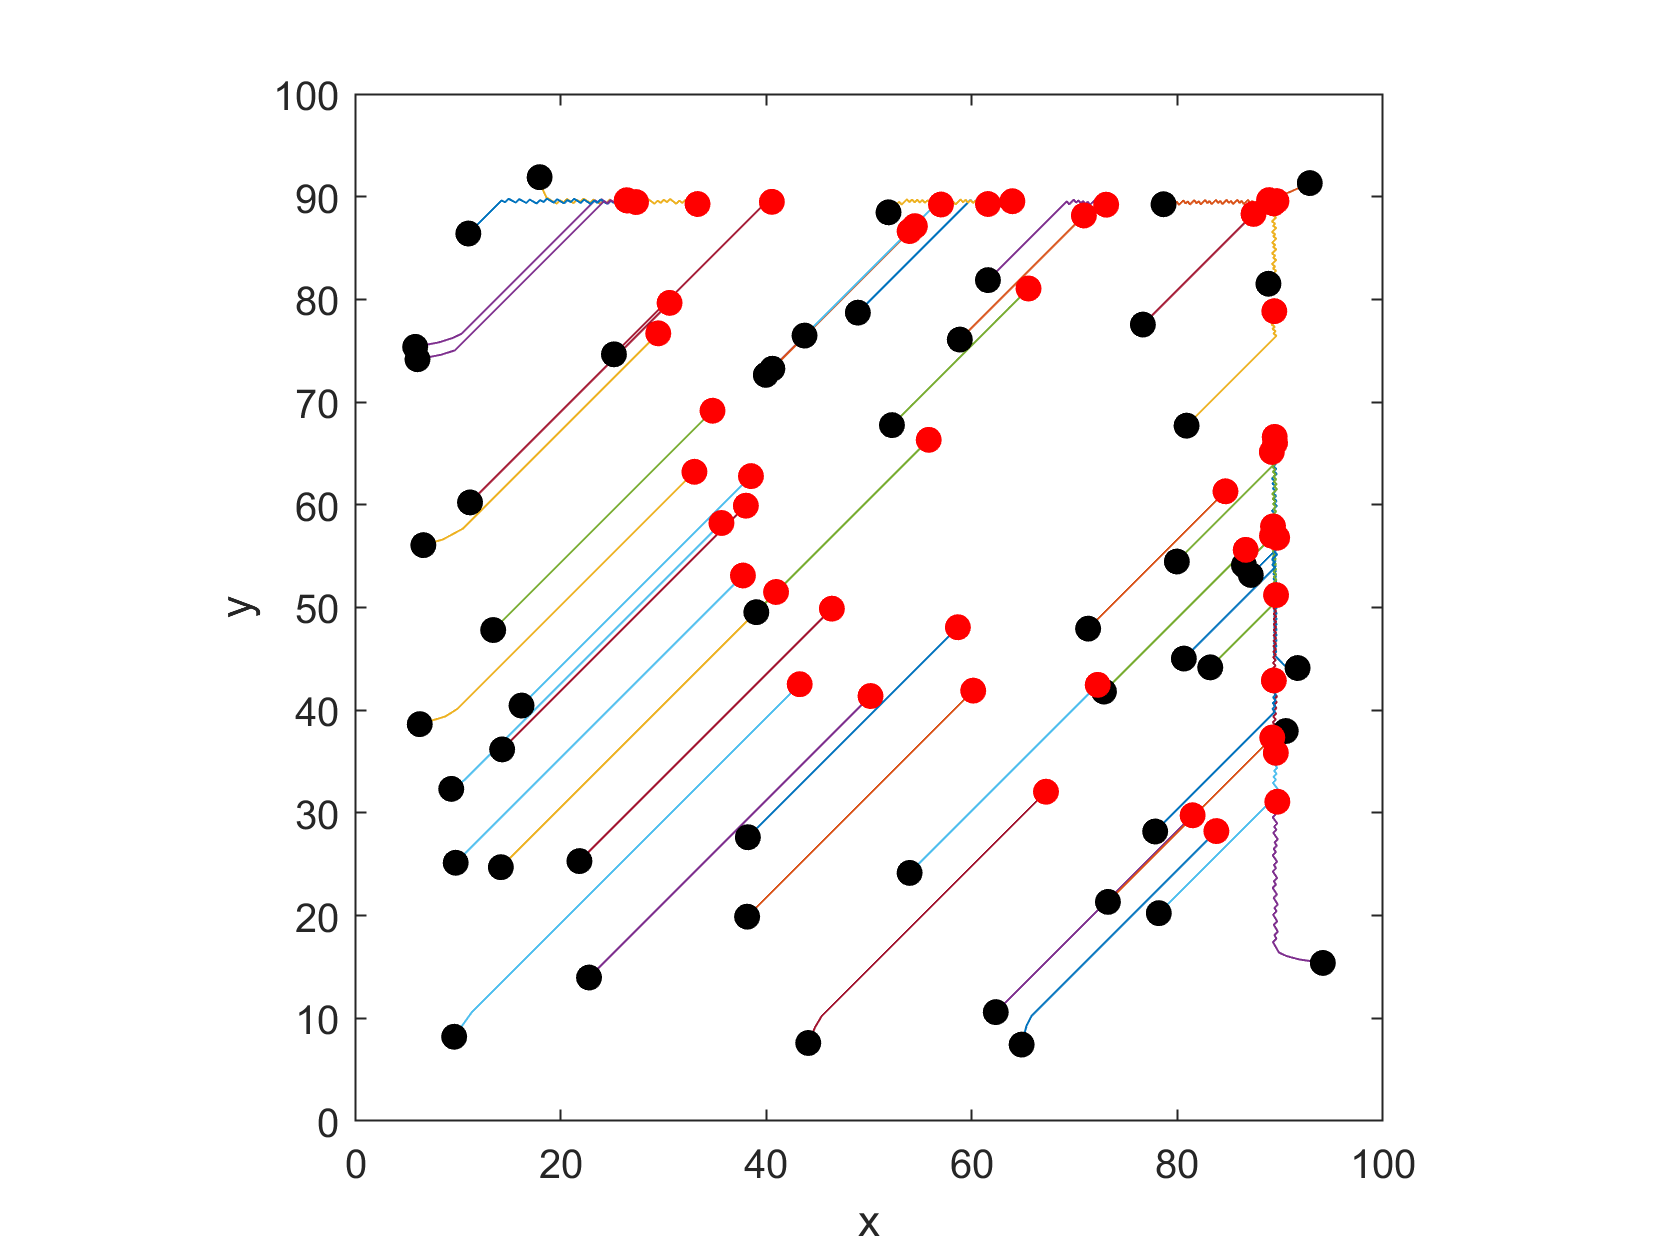

% distances between agents
Dists = []; 
for ti = 1:n_timesteps

    for ai = 1:n_agents
        for aj = 1:n_agents
            Dists = [Dists norm(squeeze(XY_all(ai,ti,:)) - squeeze(XY_all(aj, ti,:)))]; 
        end
    end
end

figure; 
histogram(Dists)

## Demo 3: pheromones

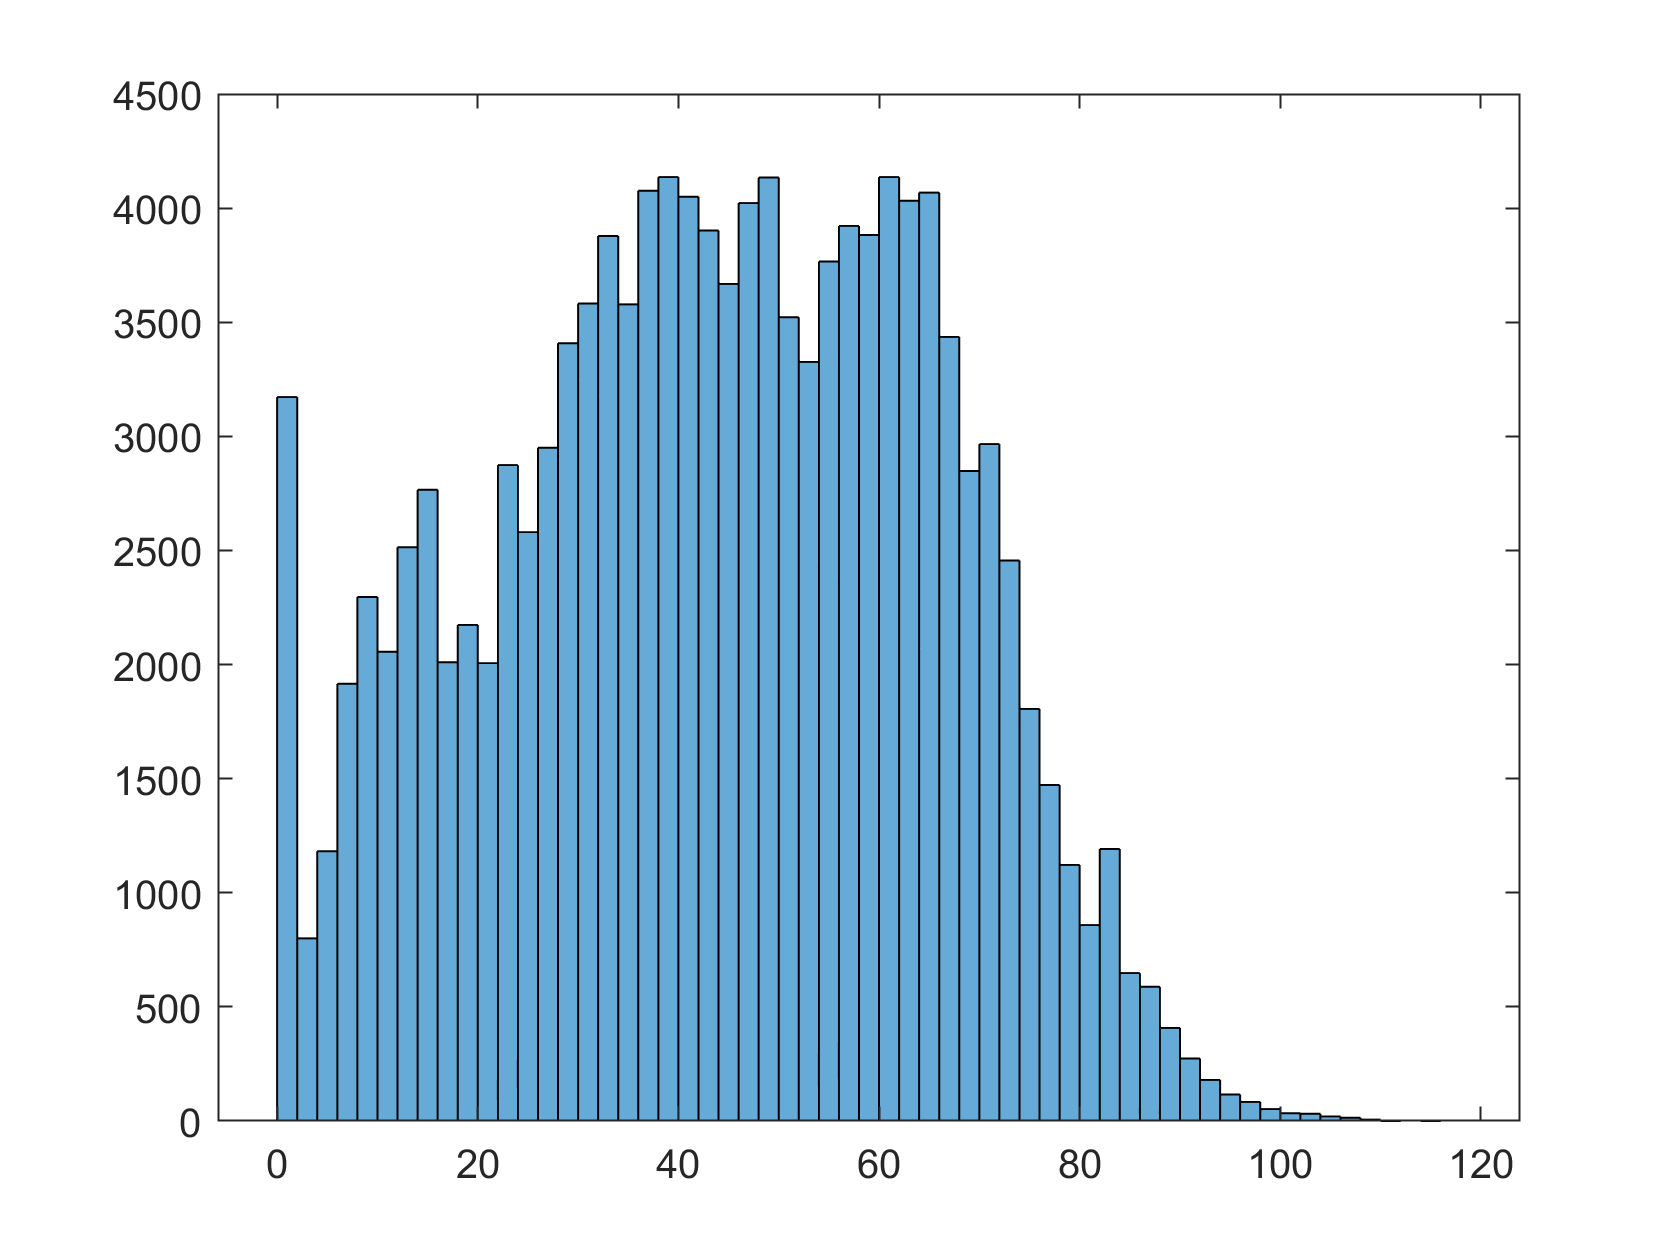

% parameters
n_agents = 50; % also show 500
n_timesteps = 20;

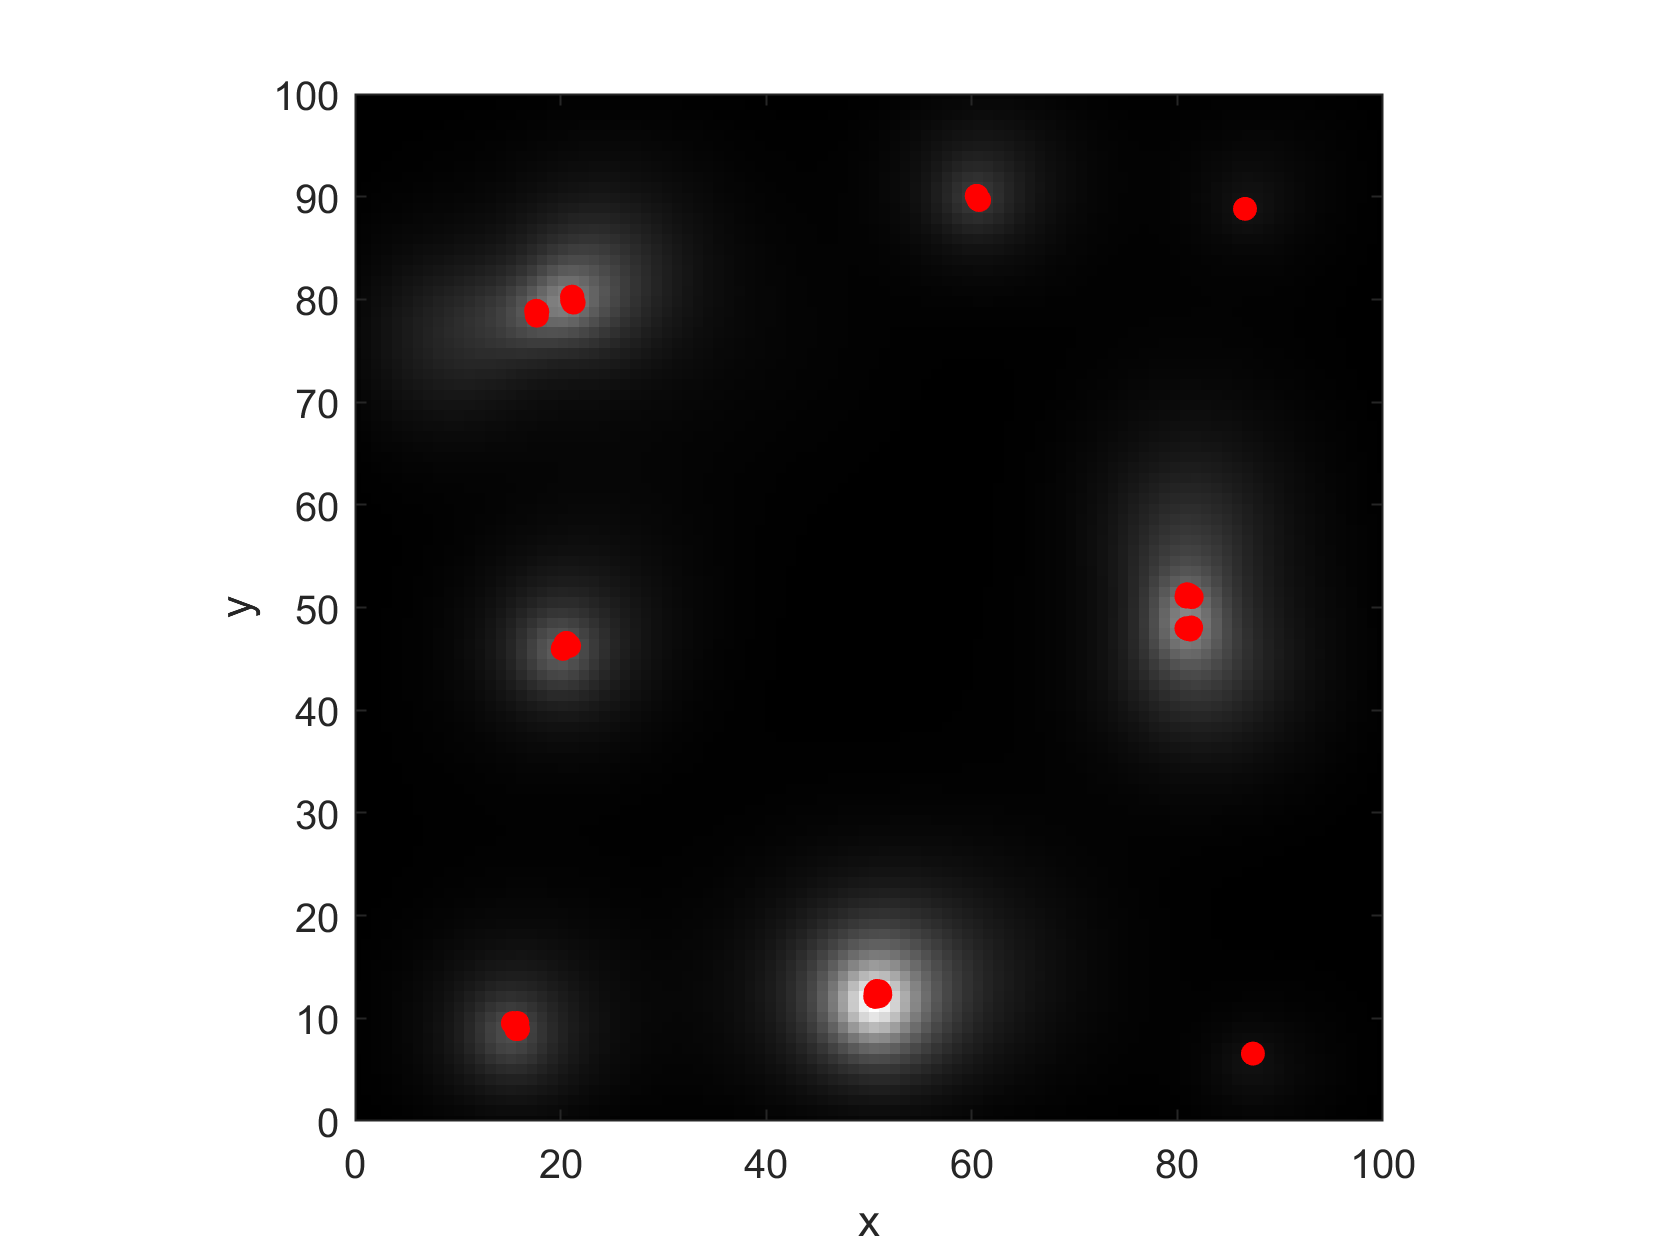

xy_max = 100;
start_pos_min = 0;
start_pos_max = xy_max;
type_of_agents = 'seek_odor';
env_type = 'pheromone'; 
sensory_range = 10; % also show 20
plot_realtime = 1; 

XY_all = simulate_agents(n_agents, n_timesteps, xy_max, start_pos_min, start_pos_max, ...
    type_of_agents, env_type, sensory_range, plot_realtime);

% trajectory plot
figure
plot_trajectories(XY_all, xy_max)

## Exercises 3

- Observe what the behavior looks like for a few different combinations of the n_agents and sensory_range. Does the final number of clusters appear to depend more on the number of agents, or their sensory ranges? 

- Design and run an experiment to test the dependency of the number of clusters on n_agents and sensory_range. Plot the results of your experiments. There is the scaffolding of some code below, and feel free to use an LLM for help. 

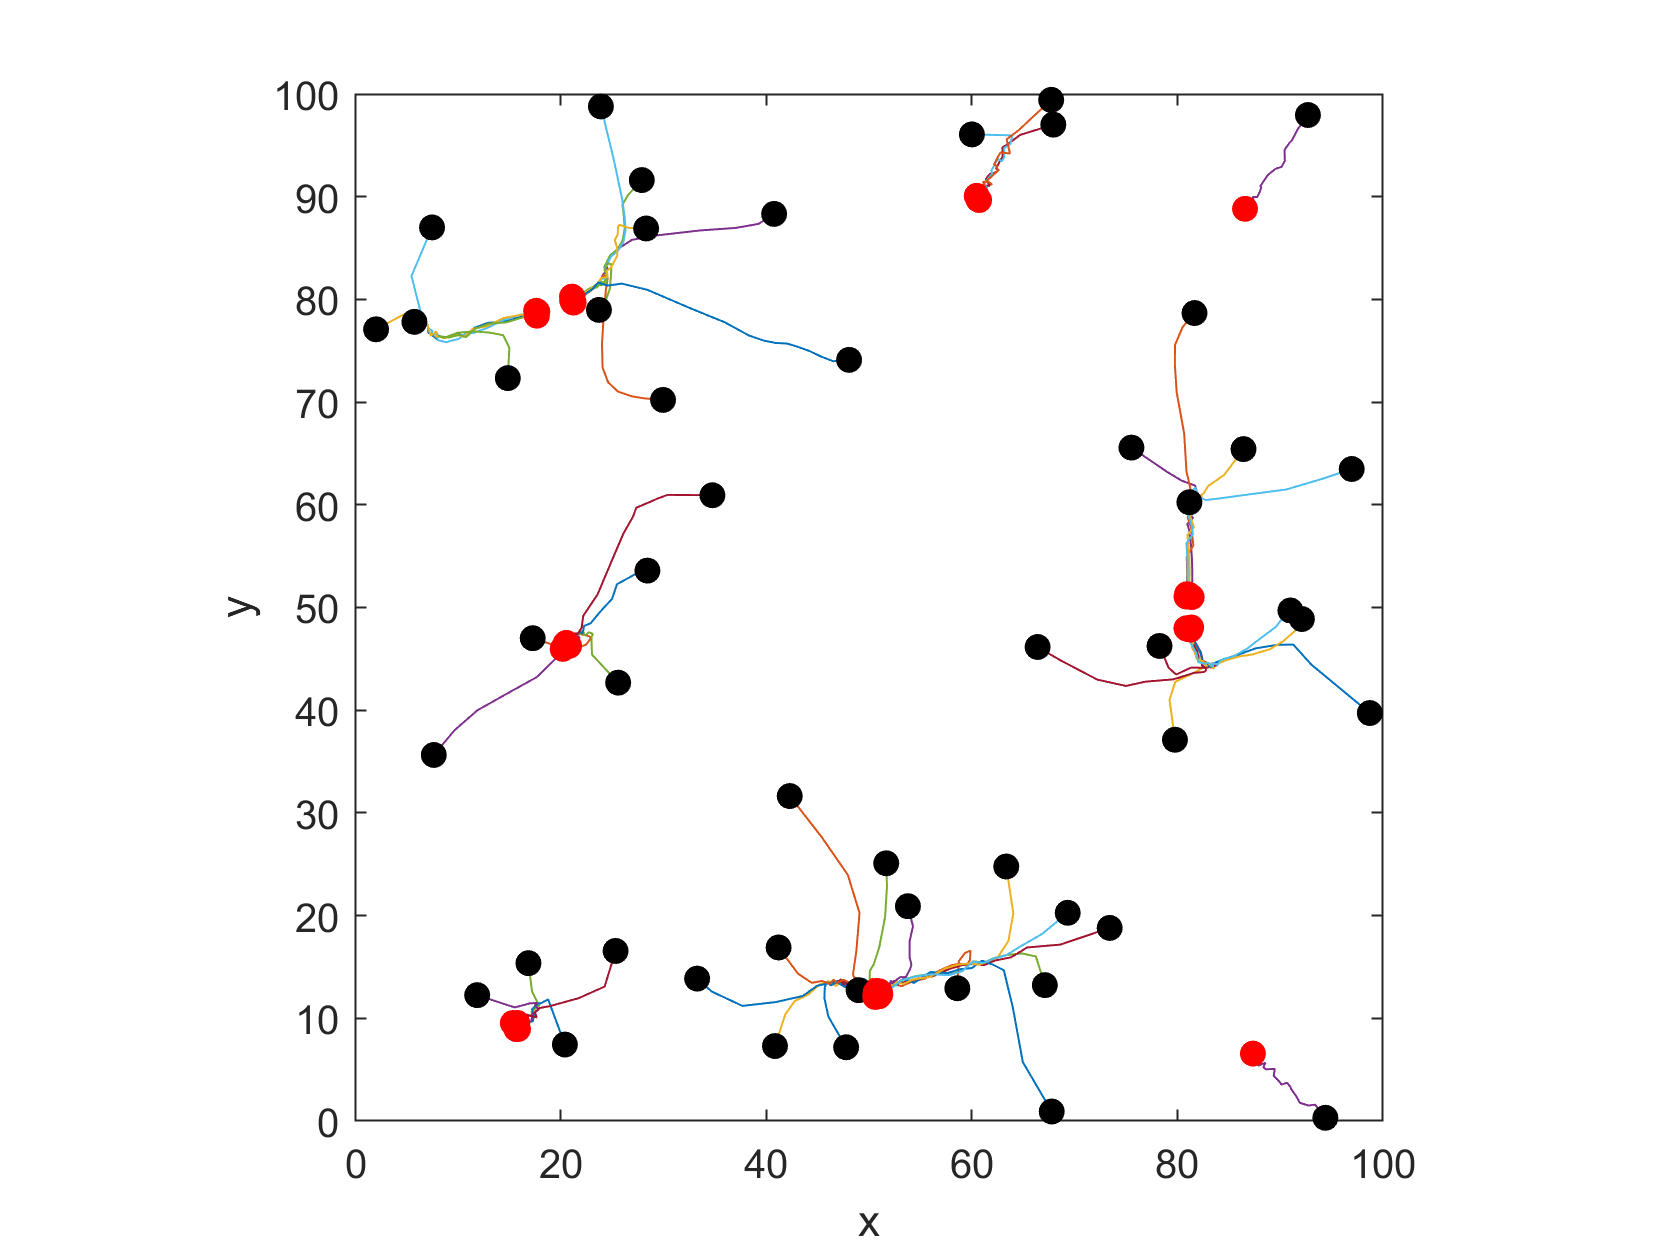

% insert your results
n_agents_to_test = []; 
sensory_range_to_test = []; 

resulting_number_clusters = []; 

figure; 
plot(n_agents_to_test, resulting_number_clusters, '.')
% remember to label your axes
% also plot the # clusters as a function of sensory range 

## Demo 4: more complex behavior

% parameters
n_agents = 100;
n_timesteps = 50;
xy_max = 100;
start_pos_min = 0;
start_pos_max = xy_max;
type_of_agents = 'elm_try_something_new';
env_type = 'pheromone'; 
sensory_range = 10; 
plot_realtime = 1; 

XY_all = simulate_agents(n_agents, n_timesteps, xy_max, start_pos_min, start_pos_max, ...
    type_of_agents, env_type, sensory_range, plot_realtime);

% trajectory plot
figure
plot_trajectories(XY_all, xy_max)

## Exercises 4

What is happening with these agents? Answer both at the population level, and at the level of individual agents' policies.

- Make a prediction about what would change about the behavior if you change one of the parameters. Try it. Were you correct? Explain your reasoning. 

- Create your own type of agent. Explain your reasoning, and the connection between the agents' policy and the behavior that you see. Edit the simulate_agents.m function by adding a 'your_policy' case, which you can simulate by setting type_of_agents = 'your_policy'. Feel free to modify other functions as well, keeping in mind the principles below.

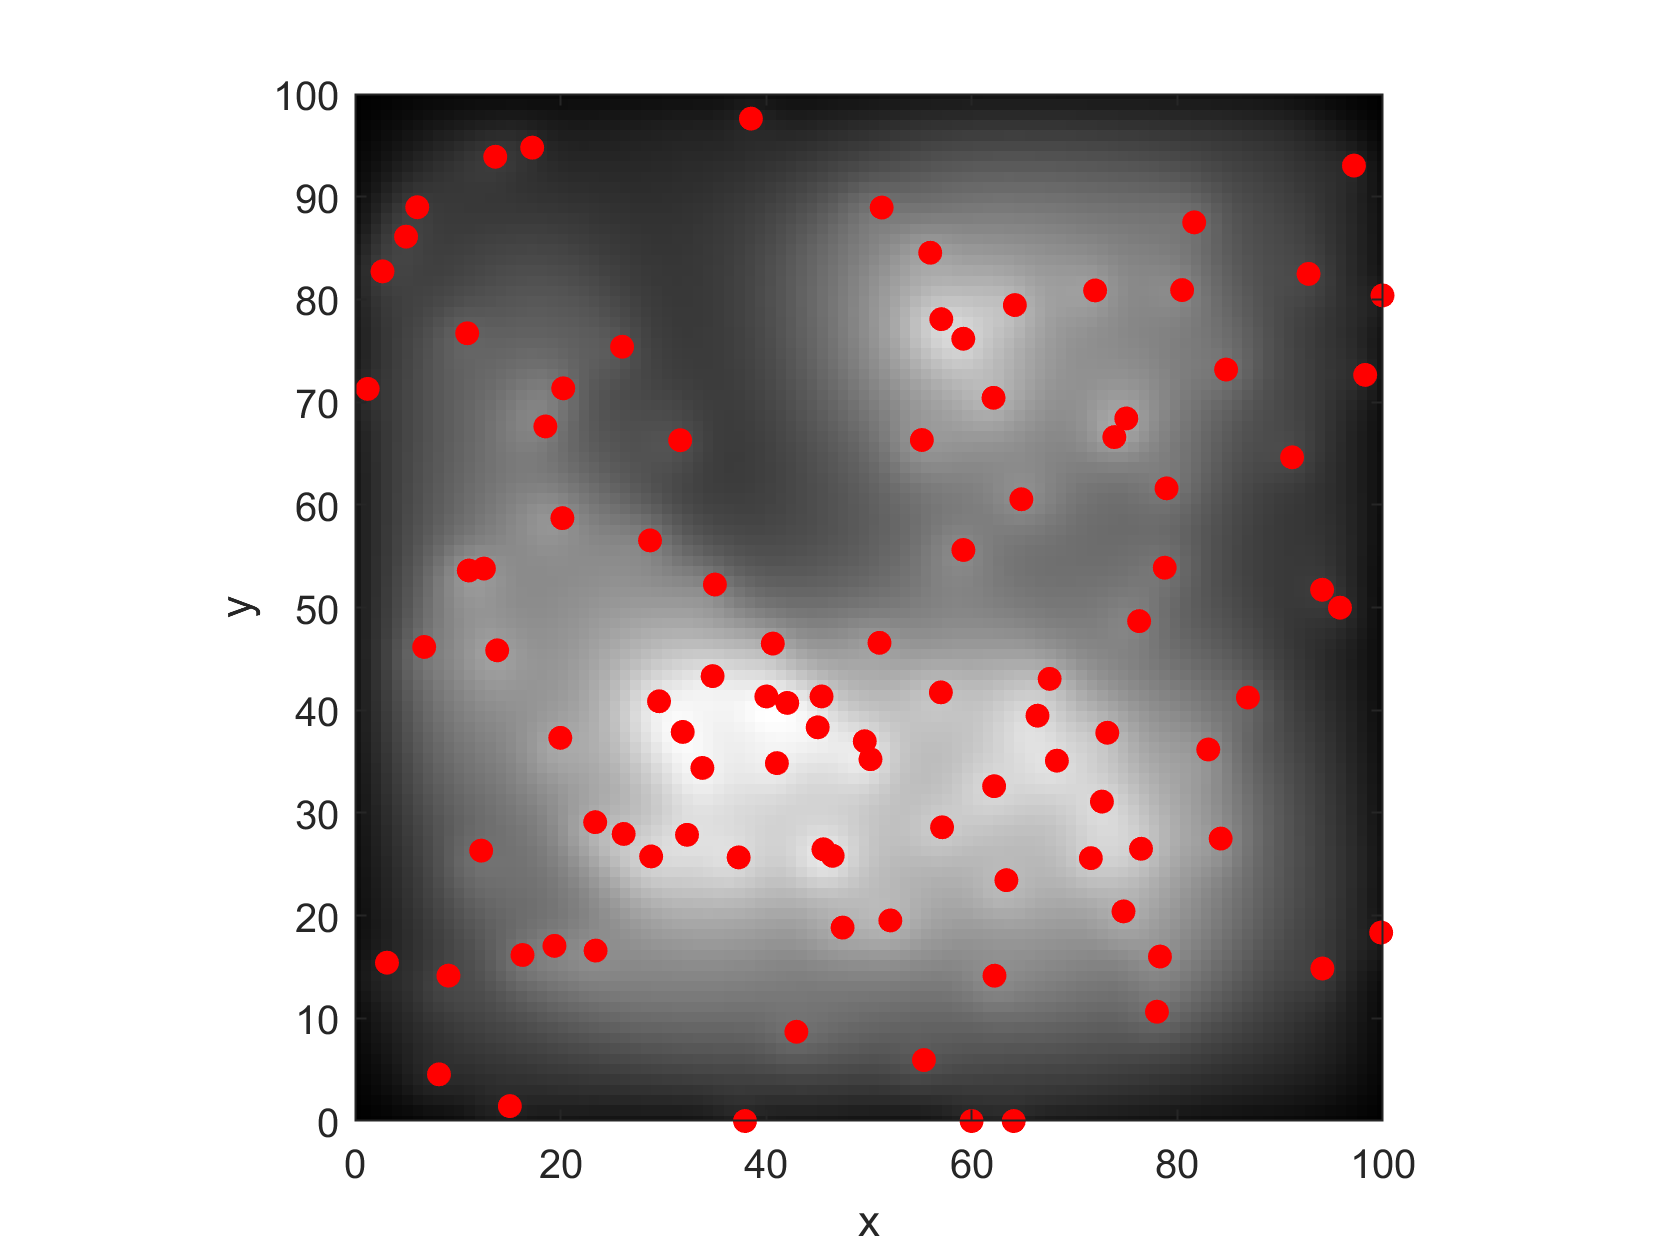

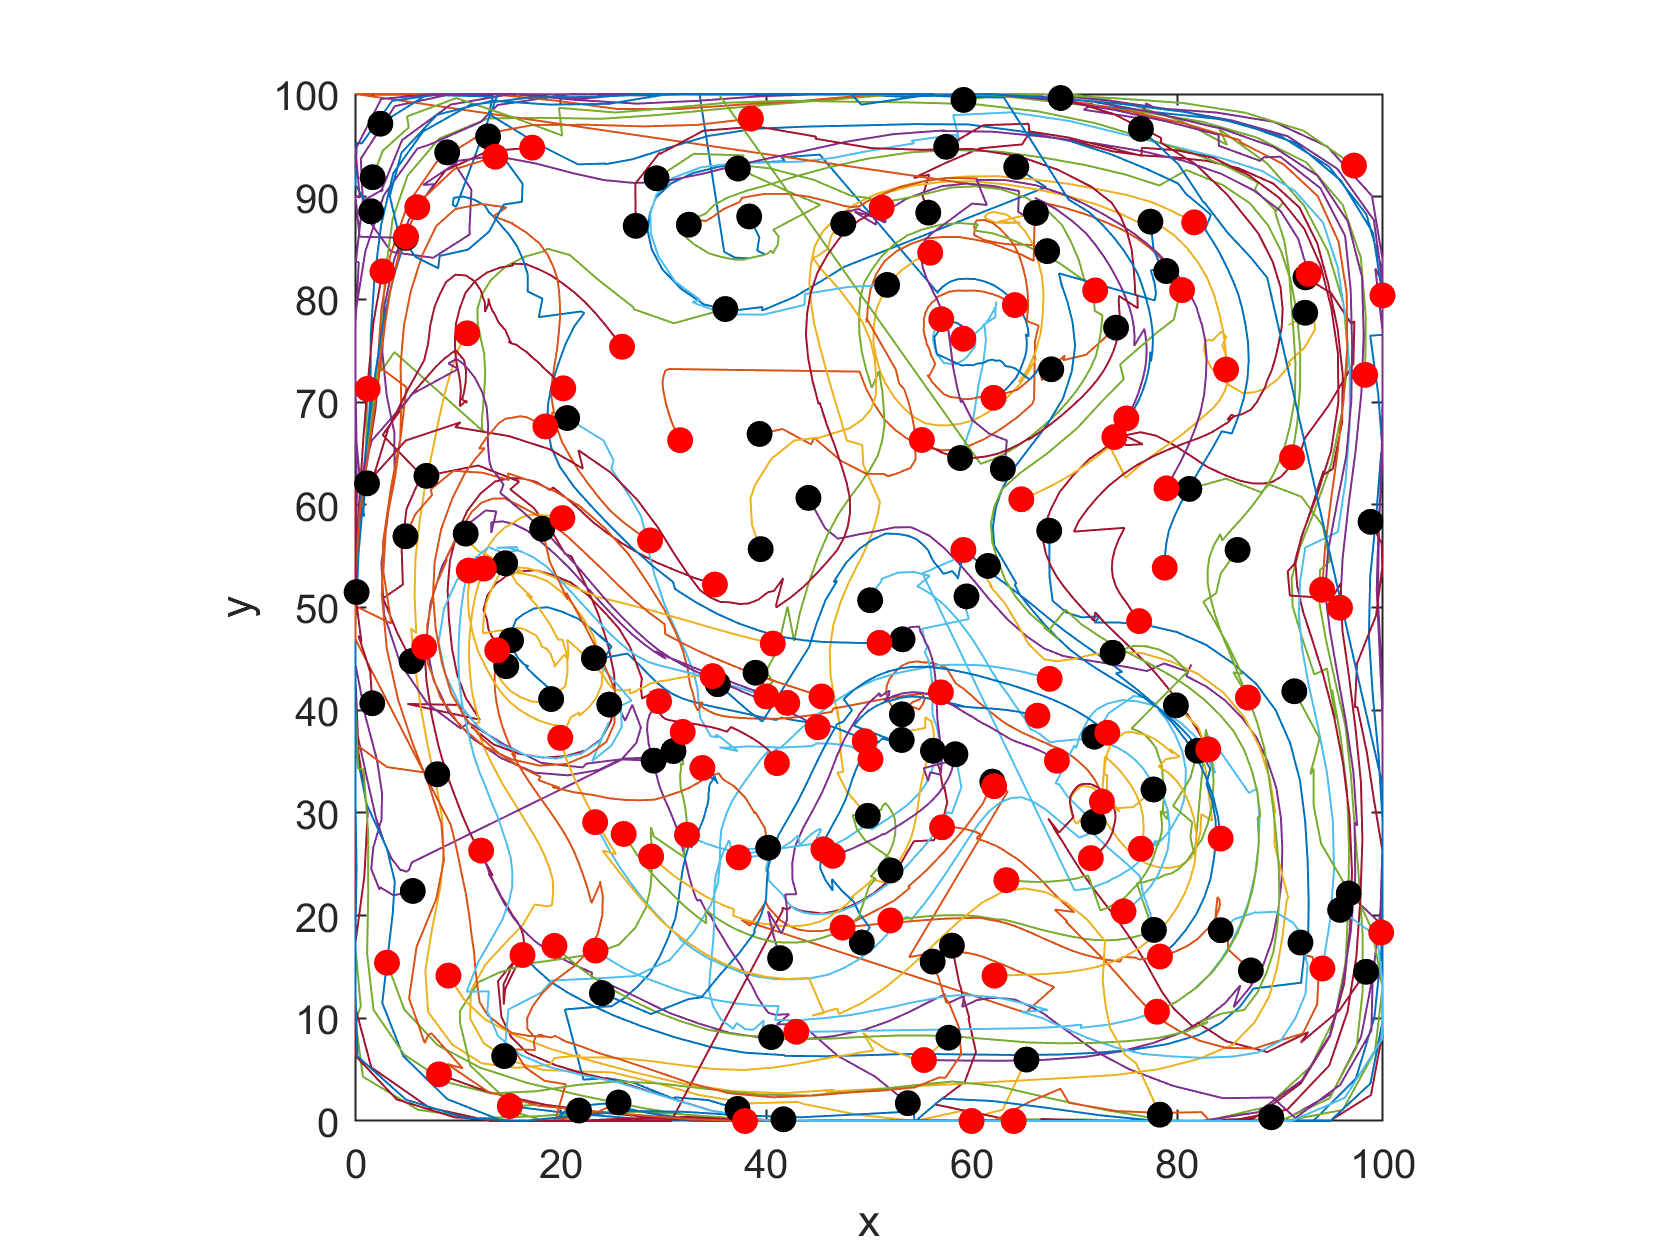

% your code here

## General principles of well-designed code

- Easy to check that it's correct

- Easy to add new functionality without breaking things

- Not too slow

Useful code repositories are 'living' collaborations among people and ideas. There's usually room for growth, which shows up as people using and contributing to code repositories. 